- Visual evaluation. Plot the time series of wind speed, wave height, water tem- perature, and air temperature from 46047. Since the data are text files with a header, in Matlab you can read with: Read the help page. You’ll want to specify a blank space delimiter between files and 2 header lines.How are missing data identified in the records? 

- Missing values are reported as '99' or '999'

Buoy2015 = readtable('Buoy2015');

Buoy2016 = readtable('Buoy2016');

BuoyData = [Buoy2015 ; Buoy2016];
BuoyData.t = datenum(BuoyData.x_YY,BuoyData.MM,BuoyData.DD);

idx = find(BuoyData.WSPD == 99);
BuoyData.WSPD(idx) = nan;
idx = find(BuoyData.WVHT == 99);
BuoyData.WVHT(idx) = nan;
idx = find(BuoyData.WTMP == 999);
BuoyData.WTMP(idx) = nan;
idx = find(BuoyData.ATMP == 999);
BuoyData.ATMP(idx) = nan;

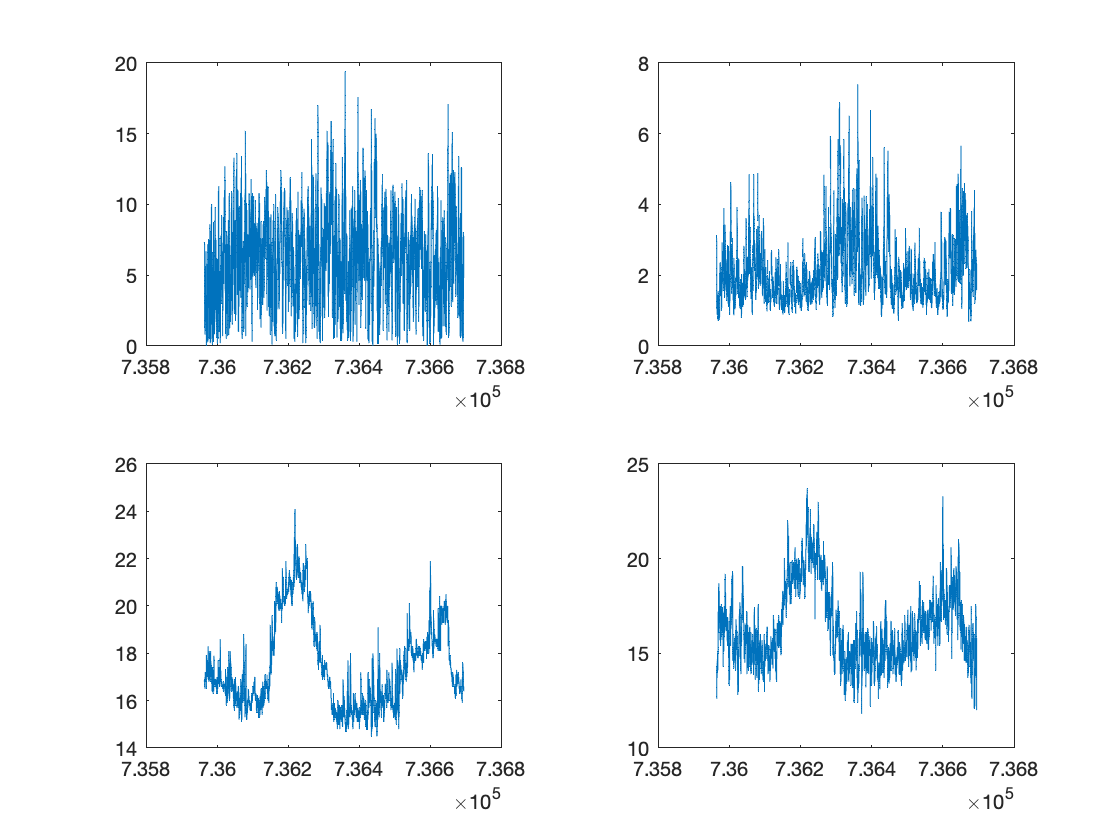

figure(1)
clf
tiledlayout(2,2)
% xticks(datenum(2015:2017,1,1))
% xticklabels(datenum(2015:2017,1,1))

nexttile
plot(BuoyData.t,BuoyData.WSPD)

nexttile
plot(BuoyData.t,BuoyData.WVHT)

nexttile
plot(BuoyData.t,BuoyData.WTMP)

nexttile
plot(BuoyData.t,BuoyData.ATMP)

2. Monthly means. Since there’s quite a bit of variability, average the data to produce monthly means for 2015 and 2016. Plot the means for each month and standard error of the mean. Data are provided at varying frequencies, but consec- utive data are not independent. For the purposes of this problem set, let’s assume that the data provide one independent sample every 7 days. Hint: In Matlab, use: 							errorbar to plot the data with uncertainty ranges. 

- Don't have to subsample, just change the n

%means
Monthlymeans2015 = nan(12,4);
Monthlymeans2016 = nan(12,4);
Months = [datenum(2015,1:12,1) datenum(2016,1:12,1)]';
for i = 1:length(Monthlymeans2015)
    idx = find(BuoyData.MM == i & BuoyData.x_YY == 2015);
    Monthlymeans2015(i,1) = nanmean(BuoyData.WSPD(idx));
    Monthlymeans2015(i,2) = nanmean(BuoyData.WVHT(idx));
    Monthlymeans2015(i,3) = nanmean(BuoyData.WTMP(idx));
    Monthlymeans2015(i,4) = nanmean(BuoyData.ATMP(idx));
end
for i = 1:length(Monthlymeans2016)
    idx = find(BuoyData.MM == i & BuoyData.x_YY == 2016);
    Monthlymeans2016(i,1) = nanmean(BuoyData.WSPD(idx));
    Monthlymeans2016(i,2) = nanmean(BuoyData.WVHT(idx));
    Monthlymeans2016(i,3) = nanmean(BuoyData.WTMP(idx));
    Monthlymeans2016(i,4) = nanmean(BuoyData.ATMP(idx));
end
Monthlymeans = [Monthlymeans2015 ; Monthlymeans2016];
Monthlymeans = table(Monthlymeans(:,1),Monthlymeans(:,2),Monthlymeans(:,3),Monthlymeans(:,4), Months);
vars = {'WSPD','WVHT','WTMP','ATMP','Months'};
Monthlymeans.Properties.VariableNames = vars;

%std error of mean assuming N = 1 sample/7 days, 4/month
for i = 1:length(Monthlymeans2015)
    idx = find(BuoyData.MM == i & BuoyData.x_YY == 2015);
    N = 4;%length(idx);
    Monthlymeans2015(i,1) = nanstd(BuoyData.WSPD(idx))/sqrt(N);
    Monthlymeans2015(i,2) = nanstd(BuoyData.WVHT(idx))/sqrt(N);
    Monthlymeans2015(i,3) = nanstd(BuoyData.WTMP(idx))/sqrt(N);
    Monthlymeans2015(i,4) = nanstd(BuoyData.ATMP(idx))/sqrt(N);
end
for i = 1:length(Monthlymeans2016)
    idx = find(BuoyData.MM == i & BuoyData.x_YY == 2016);
    N = 5;%length(idx);
    Monthlymeans2016(i,1) = nanstd(BuoyData.WSPD(idx))/sqrt(N);
    Monthlymeans2016(i,2) = nanstd(BuoyData.WVHT(idx))/sqrt(N);
    Monthlymeans2016(i,3) = nanstd(BuoyData.WTMP(idx))/sqrt(N);
    Monthlymeans2016(i,4) = nanstd(BuoyData.ATMP(idx))/sqrt(N);
end
Monthlyerror = [Monthlymeans2015 ; Monthlymeans2016];
Monthlyerror = table(Monthlyerror(:,1),Monthlyerror(:,2),Monthlyerror(:,3),Monthlyerror(:,4), Months);
vars = {'WSPD','WVHT','WTMP','ATMP','Months'};
Monthlyerror.Properties.VariableNames = vars;

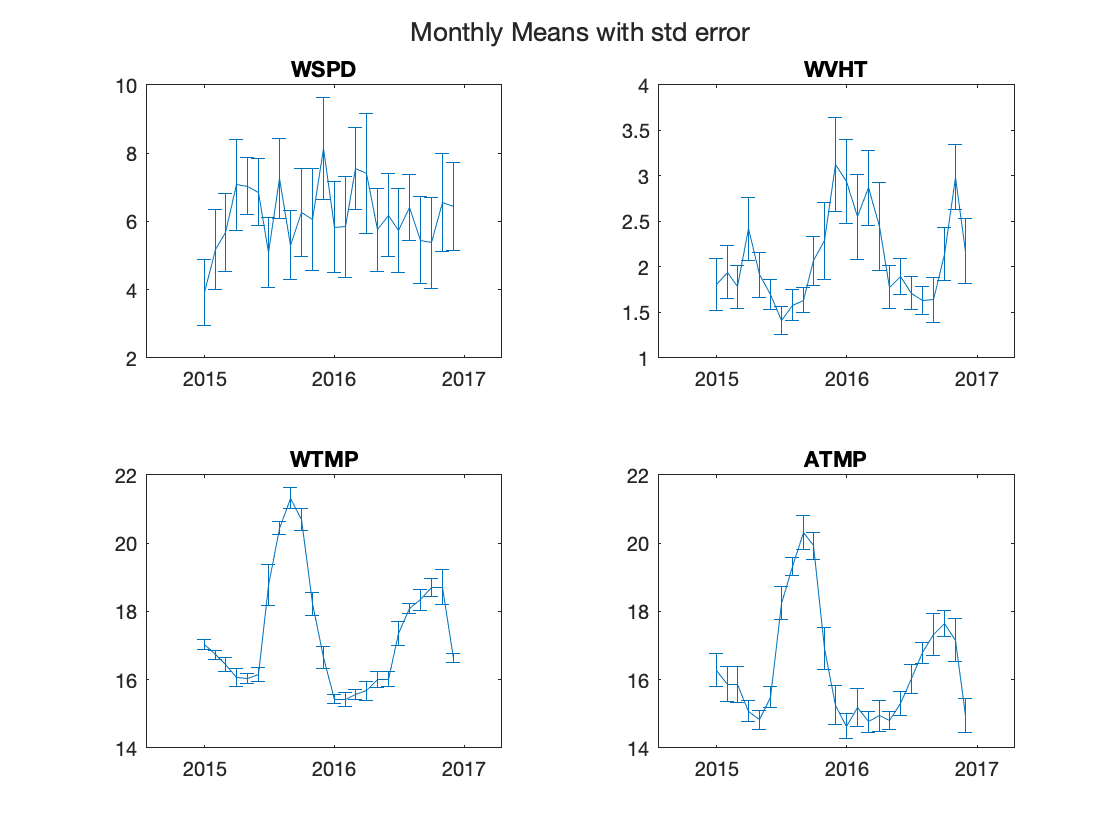

x = 1:1:24;
figure(2)
clf
m = tiledlayout(2,2);
title(m,'Monthly Means with std error')
nexttile
errorbar(Monthlymeans.Months,Monthlymeans.WSPD,Monthlyerror.WSPD)
title('WSPD')
datetick('x','keeplimits')
nexttile
errorbar(Monthlymeans.Months,Monthlymeans.WVHT,Monthlyerror.WVHT)
title('WVHT')
datetick('x','keeplimits')
nexttile
errorbar(Monthlymeans.Months,Monthlymeans.WTMP,Monthlyerror.WTMP)
title('WTMP')
datetick('x','keeplimits')
nexttile
errorbar(Monthlymeans.Months,Monthlymeans.ATMP,Monthlyerror.ATMP)
title('ATMP')
datetick('x','keeplimits')

3. Least-squares fit. Treating the two years separately, least-squares fit a mean and an annual cycle to the four data records. What is the mean, and what is the amplitude of the annual cycle? (Total amplitude should be determined from the square root of the sum of the squares of the sine and cosine amplitudes.) Are the fitted coefficients similar for the two years? 

- The fitted coefficients are similar for both years

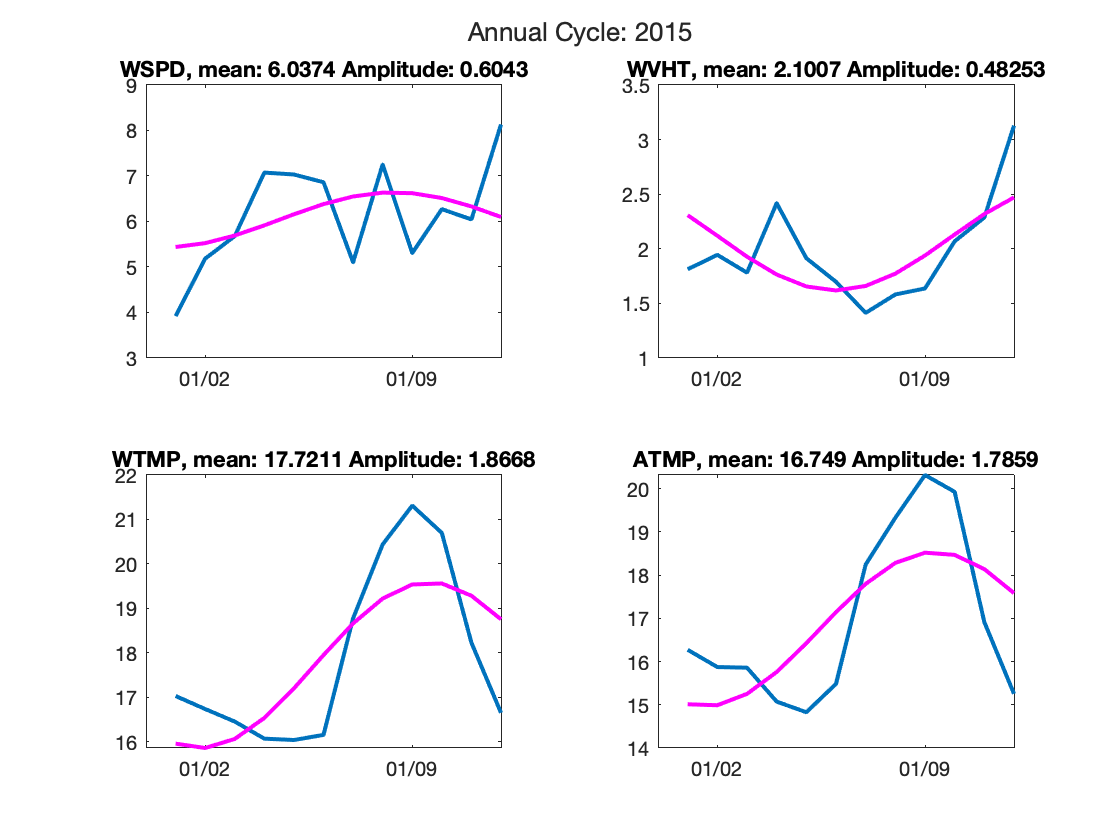

chisquared_2015 = nan(1,8);
chisquared_2016 = nan(1,8);
%1-4 annual cycle, 5-8 semi-annual cycle
P=12.4/24;
%2015
time = (1:1:12)';
A2=[ones(length(time),1) sin(2*pi*time/P) cos(2*pi*time/P)];

figure(3)
clf
m = tiledlayout(2,2);
title(m,'Annual Cycle: 2015')
nexttile
data = Monthlymeans.WSPD(1:12,:);
x2 = inv(A2'*A2)*A2'*data;
B = x2(1);
A = sqrt(sum(x2(2:end).^2));
chisquared_2015(1) = sum((data-(A2*x2)).^2)/(nanstd(data)/sqrt(N));
plot(time,data,time,A2*x2,'m','LineWidth',2)
title(['WSPD, mean: ', num2str(B), ' Amplitude: ' ,num2str(A)])
datetick('x','keeplimits')

nexttile
data = Monthlymeans.WVHT(1:12,:);
x2 = inv(A2'*A2)*A2'*data;
B = x2(1);
A = sqrt(sum(x2(2:end).^2));
chisquared_2015(2) = sum((data-(A2*x2)).^2)/(nanstd(data)/sqrt(N));
plot(time,data,time,A2*x2,'m','LineWidth',2)
title(['WVHT, mean: ', num2str(B), ' Amplitude: ' ,num2str(A)])
datetick('x','keeplimits')

nexttile
data = Monthlymeans.WTMP(1:12,:);
x2 = inv(A2'*A2)*A2'*data;
B = x2(1);
A = sqrt(sum(x2(2:end).^2));
chisquared_2015(3) = sum((data-(A2*x2)).^2)/(nanstd(data)/sqrt(N));
plot(time,data,time,A2*x2,'m','LineWidth',2)
title(['WTMP, mean: ', num2str(B), ' Amplitude: ' ,num2str(A)])
datetick('x','keeplimits')

nexttile
data = Monthlymeans.ATMP(1:12,:);
x2 = inv(A2'*A2)*A2'*data;
B = x2(1);
A = sqrt(sum(x2(2:end).^2));
chisquared_2015(4) = sum((data-(A2*x2)).^2)/(nanstd(data)/sqrt(N));
plot(time,data,time,A2*x2,'m','LineWidth',2)
title(['ATMP, mean: ', num2str(B), ' Amplitude: ' ,num2str(A)])
datetick('x','keeplimits')

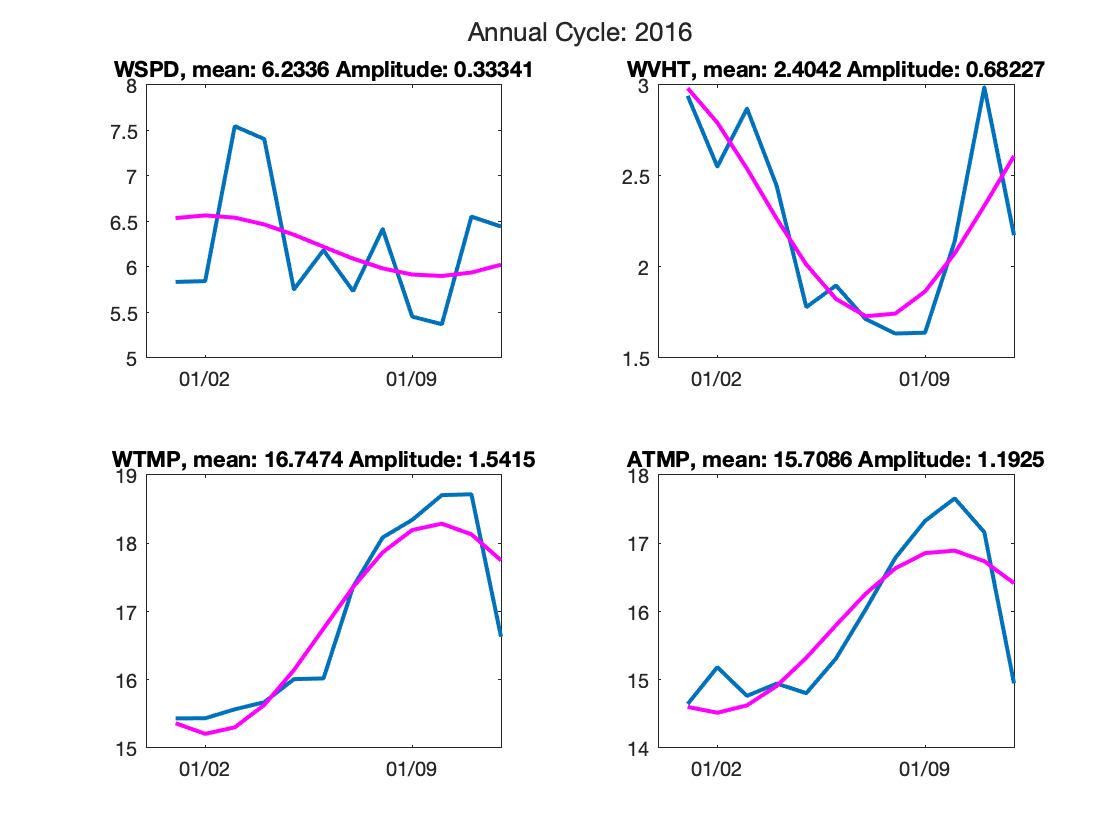


%2016
time = (1:1:12)';%Monthlymeans.Months(1:12,:);
A2=[ones(length(time),1) sin(2*pi*time/P) cos(2*pi*time/P)];

figure(4)
clf
m = tiledlayout(2,2);
title(m,'Annual Cycle: 2016')
nexttile
data = Monthlymeans.WSPD(13:24,:);
x2 = inv(A2'*A2)*A2'*data;
B = x2(1);
A = sqrt(sum(x2(2:end).^2));
chisquared_2016(1) = sum((data-(A2*x2)).^2)/(nanstd(data)/sqrt(N));
plot(time,data,time,A2*x2,'m','LineWidth',2)
title(['WSPD, mean: ', num2str(B), ' Amplitude: ' ,num2str(A)])
datetick('x','keeplimits')

nexttile
data = Monthlymeans.WVHT(13:24,:);
x2 = inv(A2'*A2)*A2'*data;
B = x2(1);
A = sqrt(sum(x2(2:end).^2));
chisquared_2016(2) = sum((data-(A2*x2)).^2)/(nanstd(data)/sqrt(N));
plot(time,data,time,A2*x2,'m','LineWidth',2)
title(['WVHT, mean: ', num2str(B), ' Amplitude: ' ,num2str(A)])
datetick('x','keeplimits')

nexttile
data = Monthlymeans.WTMP(13:24,:);
x2 = inv(A2'*A2)*A2'*data;
B = x2(1);
A = sqrt(sum(x2(2:end).^2));
chisquared_2016(3) = sum((data-(A2*x2)).^2)/(nanstd(data)/sqrt(N));
plot(time,data,time,A2*x2,'m','LineWidth',2)
title(['WTMP, mean: ', num2str(B), ' Amplitude: ' ,num2str(A)])
datetick('x','keeplimits')

nexttile
data = Monthlymeans.ATMP(13:24,:);
x2 = inv(A2'*A2)*A2'*data;
B = x2(1);
A = sqrt(sum(x2(2:end).^2));
chisquared_2016(4) = sum((data-(A2*x2)).^2)/(nanstd(data)/sqrt(N));
plot(time,data,time,A2*x2,'m','LineWidth',2)
title(['ATMP, mean: ', num2str(B), ' Amplitude: ' ,num2str(A)])
datetick('x','keeplimits')

4. Least-squares fit a semi-annual cycle. Augment your annual cycle least- squares fit with a semi-annual cycle. What is the amplitude of the semi-annual cycle? Does the augmented fit give you a different annual cycle? 

- The semi annual cycle gives a more accurate annual cycle because it accounts for a warm and cold period of the year

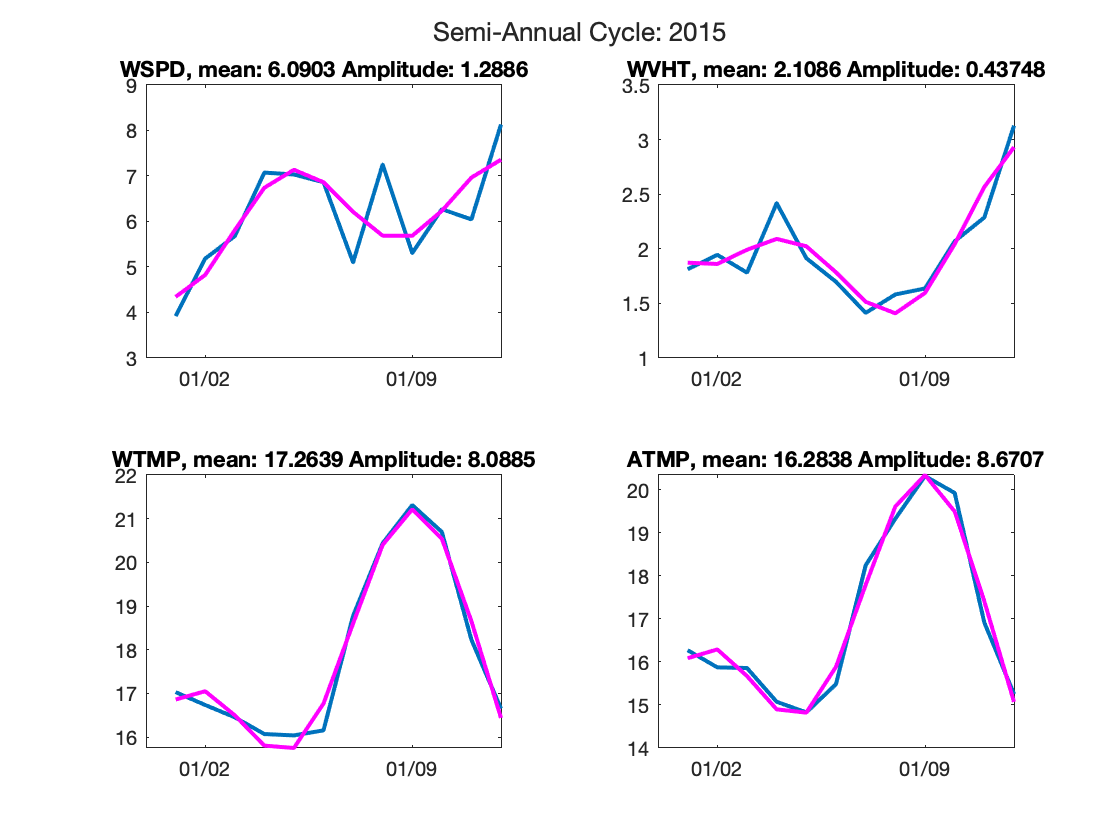

P=12.4/24;
%2015
time = (1:1:12)';
A2=[ones(length(time),1) sin(2*pi*time/P) cos(2*pi*time/P) sin(4*pi*time/P) cos(4*pi*time/P)];

figure(5)
clf
m = tiledlayout(2,2);
title(m,'Semi-Annual Cycle: 2015')
nexttile
data = Monthlymeans.WSPD(1:12,:);
x2 = inv(A2'*A2)*A2'*data;
B = x2(1);
A = sqrt(sum(x2(2:end).^2));
chisquared_2015(5) = sum((data-(A2*x2)).^2)/(nanstd(data)/sqrt(N));
plot(time,data,time,A2*x2,'m','LineWidth',2)
title(['WSPD, mean: ', num2str(B), ' Amplitude: ' ,num2str(A)])
datetick('x','keeplimits')

nexttile
data = Monthlymeans.WVHT(1:12,:);
x2 = inv(A2'*A2)*A2'*data;
B = x2(1);
A = sum(x2(2:end).^2);
chisquared_2015(6) = sum((data-(A2*x2)).^2)/(nanstd(data)/sqrt(N));
plot(time,data,time,A2*x2,'m','LineWidth',2)
title(['WVHT, mean: ', num2str(B), ' Amplitude: ' ,num2str(A)])
datetick('x','keeplimits')

nexttile
data = Monthlymeans.WTMP(1:12,:);
x2 = inv(A2'*A2)*A2'*data;
B = x2(1);
A = sum(x2(2:end).^2);
chisquared_2015(7) = sum((data-(A2*x2)).^2)/(nanstd(data)/sqrt(N));
plot(time,data,time,A2*x2,'m','LineWidth',2)
title(['WTMP, mean: ', num2str(B), ' Amplitude: ' ,num2str(A)])
datetick('x','keeplimits')

nexttile
data = Monthlymeans.ATMP(1:12,:);
x2 = inv(A2'*A2)*A2'*data;
B = x2(1);
A = sum(x2(2:end).^2);
chisquared_2015(8) = sum((data-(A2*x2)).^2)/(nanstd(data)/sqrt(N));
plot(time,data,time,A2*x2,'m','LineWidth',2)
title(['ATMP, mean: ', num2str(B), ' Amplitude: ' ,num2str(A)])
datetick('x','keeplimits')

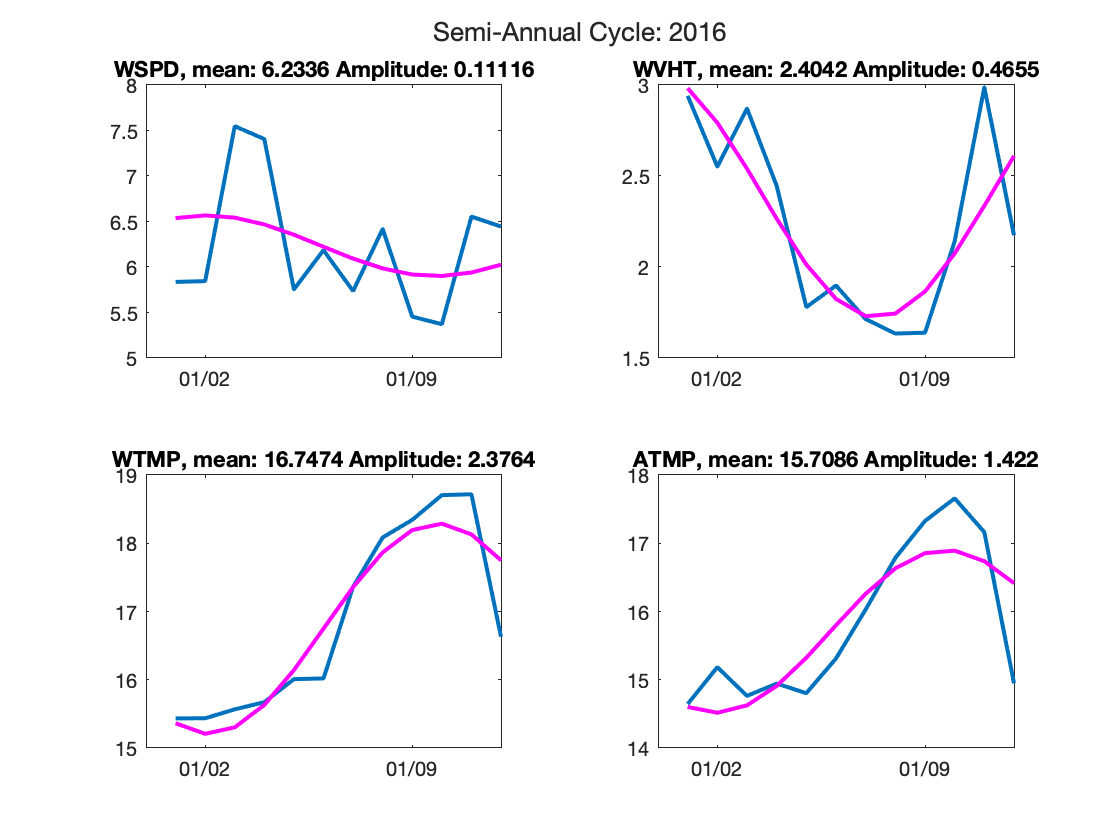


%2016
time = (1:1:12)';%Monthlymeans.Months(1:12,:);
A2=[ones(length(time),1) sin(2*pi*time/P) cos(2*pi*time/P)];

figure(6)
clf
m = tiledlayout(2,2);
title(m,'Semi-Annual Cycle: 2016')
nexttile
data = Monthlymeans.WSPD(13:24,:);
x2 = inv(A2'*A2)*A2'*data;
B = x2(1);
A = sum(x2(2:end).^2);
chisquared_2016(5) = sum((data-(A2*x2)).^2)/(nanstd(data)/sqrt(N));
plot(time,data,time,A2*x2,'m','LineWidth',2)
title(['WSPD, mean: ', num2str(B), ' Amplitude: ' ,num2str(A)])
datetick('x','keeplimits')

nexttile
data = Monthlymeans.WVHT(13:24,:);
x2 = inv(A2'*A2)*A2'*data;
B = x2(1);
A = sum(x2(2:end).^2);
chisquared_2016(6) = sum((data-(A2*x2)).^2)/(nanstd(data)/sqrt(N));
plot(time,data,time,A2*x2,'m','LineWidth',2)
title(['WVHT, mean: ', num2str(B), ' Amplitude: ' ,num2str(A)])
datetick('x','keeplimits')

nexttile
data = Monthlymeans.WTMP(13:24,:);
x2 = inv(A2'*A2)*A2'*data;
B = x2(1);
A = sum(x2(2:end).^2);
chisquared_2016(7) = sum((data-(A2*x2)).^2)/(nanstd(data)/sqrt(N));
plot(time,data,time,A2*x2,'m','LineWidth',2)
title(['WTMP, mean: ', num2str(B), ' Amplitude: ' ,num2str(A)])
datetick('x','keeplimits')

nexttile
data = Monthlymeans.ATMP(13:24,:);
x2 = inv(A2'*A2)*A2'*data;
B = x2(1);
A = sum(x2(2:end).^2);
chisquared_2016(8) = sum((data-(A2*x2)).^2)/(nanstd(data)/sqrt(N));
plot(time,data,time,A2*x2,'m','LineWidth',2)
title(['ATMP, mean: ', num2str(B), ' Amplitude: ' ,num2str(A)])
datetick('x','keeplimits')

5. **χ2 and the misfit.** What is the squared misfit of your least-squares fits? You can compute this as does the misfit change if you fit with an annual cycle only or with an annual plus semi-annnual cycle? Use the χ2 distribution to evaluate whether your fits are improved by adding the semi-annual fit? On the basis of the χ2 distribution, are you overfitting the data, or choosing the wrong model for your data? How would your results change if you assumed that you had one independent sample (i.e. one degree of freedom) per day, instead of one per week?

Misfit = N-M, N = samples, M = functions

N = 4

M = 3, Annual Cycle

M = 5, Semi-Annual Cycle

Misfit_Annual = 4 - 3 = 1

Misfit_Semi_Annual = 4 - 5 = -1

We are overfitting/choosing the wrong model assuming a sample once every week. If we were to assume 365 independent samples per year, we would be able to use the semi-annual cycle to acheive better results without overfitting the model.

I am confused why chisquared_2016 annual and semi-annual results are the same when chisquared_2015 are different.

chisquared_2015

chisquared_2015 =    25.1663    6.8684   20.8799   24.8706   10.8671    1.6463    1.0833    1.3397


chisquared_2016

chisquared_2016 =    14.7556    4.0860    4.2412    8.2637   14.7556    4.0860    4.2412    8.2637


%in order: Annual WSPD, WVHT, WTMP, ATMP - SemiAnnual WSPD, WVHT, WTMP, ATMP
